przed wykonaniem zadan włacz w matlabie log za pomoca polecenia: 

diary(0log indeks lab30). Podaj nr Twojego indeksu

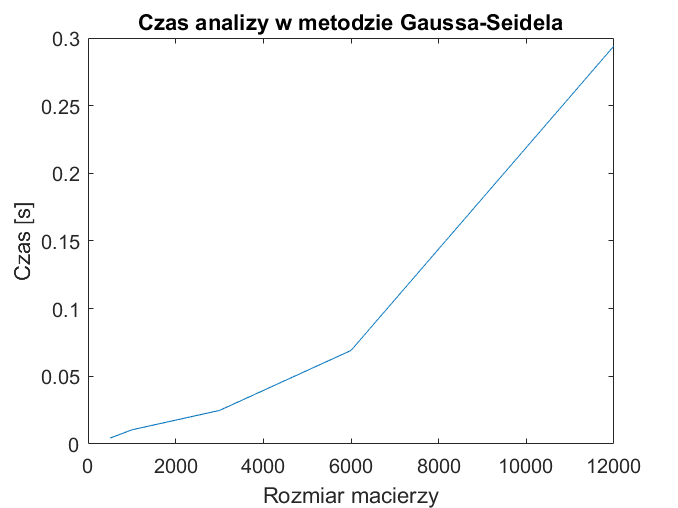

diary('log_184698_lab3')

N = [500, 1000, 3000, 6000, 12000];
d = 0.85;
density = 10;
my_index = 184698;

norm_res = [];
residuum = 10^(-14);
k = 1;

for i = 1:length(N)
    [Edges] = generate_network(N(i), density);
    b = zeros(N(i),1);
    b(:,1) = (1-d)/ N(i); %wektor b wyznaczony ze wzoru podanego w instrukcji
    I = speye(N(i));
    B = sparse(Edges(2,:),Edges(1,:),1,N(i),N(i)); %tworzenie macierzy B
    l = zeros(1,N(i)); %tworzenie wektora wypełnionego zerami, z którego powstanie macierz diagonala
    tmp = 1; 
    while tmp <= N(i)
        l(tmp) = sum(B(:,tmp)); %sumowanie wartosci
        l(tmp) = 1./l(tmp);
        tmp = tmp + 1; 
    end
    %stworzenie macierzy A
    A = sparse(diag(l));
    % obliczenia
    M = sparse(I - d*B*A); %utworzenie parametru M

    L = tril(M, -1); % -1 --> macierz trójkątna dolna
    U = triu(M, 1); % -1 --> macierz trójkątna górna
    D = diag(diag(M)); % Calling diag twice returns a diagonal matrix composed of the diagonal elements of the original matrix.
    
    x = ones(N(i),1); % bo poczatkowe x(1) to same jedynki
    
    iter_counter(i) = 0; %liczenie iteracji dla i-tego przypadku
    
    DL = D + L;

    tic % poczatek pomiaru czasu
        while true
            x = -DL\(U*x)+ DL\b; %wyznaczanie przyblizenia   
            r = M*x - b;%wyznaczanie residuum

            if N(i) == 1000
                  %obliczenie wartosci normy bledu rezydualnego
                  norm_res(k) = norm(r); %funkcja norm wyznaczna normę euklidesową
                  k = k + 1;
            end 

            %jesli przekroczy wartosc to wychodzimy z petli
            if norm(r) <= residuum
                break
            end

           %liczenie liczby iteracji
           iter_counter(i) = iter_counter(i) + 1;
        end
    time_counter(i) = toc; %koniec pomiaru czasu
end

plot(N, time_counter);
ylabel("Czas [s]");
xlabel("Rozmiar macierzy");
title("Czas analizy w metodzie Gaussa-Seidela");
saveas(gcf,"ZadF_184698_1.png"); 

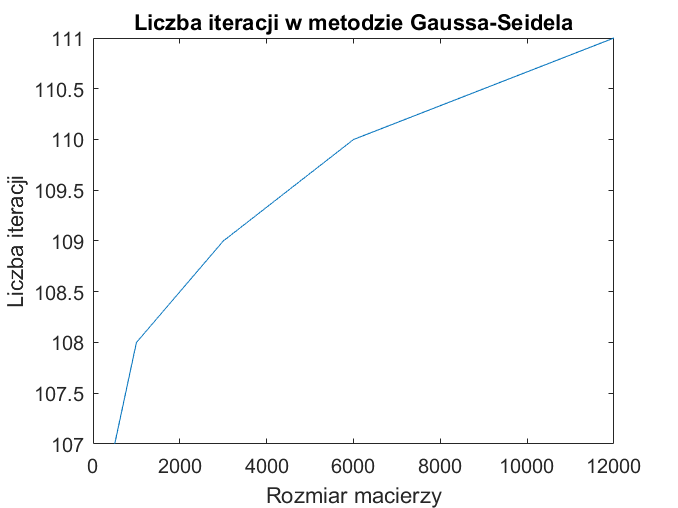

plot(N, iter_counter);
ylabel("Liczba iteracji");
xlabel("Rozmiar macierzy");
title("Liczba iteracji w metodzie Gaussa-Seidela");
saveas(gcf,"ZadF_184698_2.png"); 

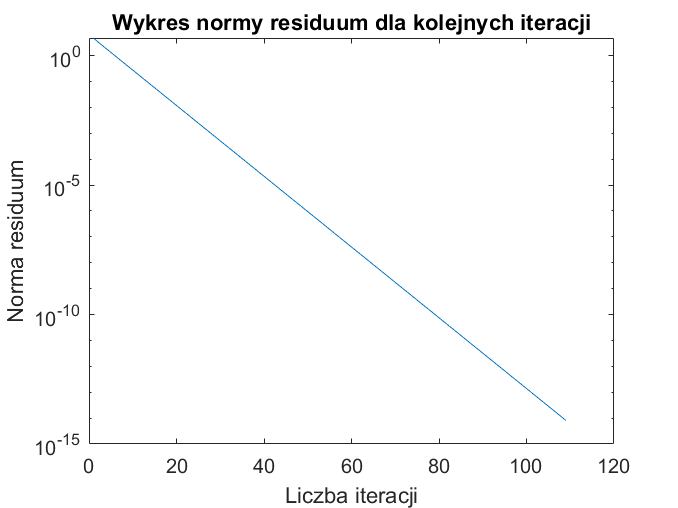

semilogy(norm_res);
ylabel("Norma residuum");
xlabel("Liczba iteracji");
title("Wykres normy residuum dla kolejnych iteracji");
saveas(gcf,"ZadF_184698_3.png"); 

def funkcji generate_network

function [Edges] = generate_network(N, density, my_index)

Edges = randi(N, 2, N * density) ;

Edges(:, find((Edges(1,:) - Edges(2,:))==0))=[];     % usuniecie linkow - gdzie strona wskazuje na sama siebie.

Edges_temp = sortrows(Edges'); % sortowanie, zeby ulatwic usniecie zdublowanych polaczen.
d_connections = find(sum(abs(Edges_temp(2:end,:) - Edges_temp(1:end-1,:)),2) == 0);   % wyszukanie zdublowanych polaczen.
Edges_temp(d_connections,:) = [];    % usuniecie zdublowanych polaczen.
Edges = Edges_temp';

Sites_uniq = unique(Edges(1,:));
nr_of_end_sites = 0;

for k = 1:N
    if ~ismember(k, Sites_uniq)
        nr_of_end_sites = nr_of_end_sites + 1;
        Edges = [Edges [[ones(1,N-1) * k]; [1:k-1 k+1:N]]];
    end
end

% disp(['* Liczba stron koncowych: ', num2str( nr_of_end_sites)])

end